%% Lecture 08: Compare Denoising Filters (Option A)
% *Image:* |rice.png| (MATLAB Image Processing Toolbox sample image), used
% as the reference |Iref|.
%
% *Degradation (fixed by the assignment):*
% |rng(42); Id = imnoise(imnoise(Iref,'gaussian',0,0.01),'salt & pepper',0.02);|
%
% *Filters applied to |Id|:*
%
% # 3x3 median filter
% # Gaussian filter, sigma = 1.5
% # 3x3 median filter followed by a Gaussian filter, sigma = 1
%
% Each result is compared with |Iref| using PSNR and SSIM. A zoomed 80x80
% region shows the remaining noise and blur. The three processed images,
% the figures and the metrics table are written to |results/|.
%
% Requires the Image Processing Toolbox (|imnoise|, |medfilt2|,
% |imgaussfilt|, |psnr|, |ssim|).

clear; close all; clc;

scriptDir = fileparts(mfilename('fullpath'));
if isempty(scriptDir)
    scriptDir = pwd;
end
resultsDir = fullfile(scriptDir, 'results');
if ~exist(resultsDir, 'dir')
    mkdir(resultsDir);
end

v = ver('images');
fprintf('MATLAB %s\n', version);

MATLAB 26.2.0.3468271 (R2026b) Update 2


fprintf('Image Processing Toolbox %s %s\n', v.Version, v.Release);

Image Processing Toolbox 26.2 (R2026b)



%% Reference and degraded image
% Gaussian noise with variance 0.01 is added first (standard deviation 0.1
% of full scale, about 25 grey levels). Then 2 % of the pixels are replaced
% by black or white impulses (salt and pepper).

Iref = imread('rice.png');
rng(42);
Id = imnoise(imnoise(Iref, 'gaussian', 0, 0.01), 'salt & pepper', 0.02);

fprintf('Iref: %dx%d %s\n', size(Iref, 1), size(Iref, 2), class(Iref));

Iref: 256x256 uint8



%% Apply the three filters
% |medfilt2| pads with zeros by default, which turns the one-pixel image
% border dark and lowers PSNR for a reason unrelated to denoising. All
% median filters here therefore use |'symmetric'| padding. |imgaussfilt|
% uses its defaults (kernel size |2*ceil(2*sigma)+1|, replicate padding).

Imed   = medfilt2(Id, [3 3], 'symmetric');
Igauss = imgaussfilt(Id, 1.5);
Icomb  = imgaussfilt(medfilt2(Id, [3 3], 'symmetric'), 1);

imwrite(Imed,   fullfile(resultsDir, 'median3x3.png'));
imwrite(Igauss, fullfile(resultsDir, 'gaussian_sigma1p5.png'));
imwrite(Icomb,  fullfile(resultsDir, 'median3x3_gaussian_sigma1.png'));

%% PSNR and SSIM against Iref
% The degraded image is included as a baseline. Higher is better for both
% metrics.

names  = {'Degraded (no filter)'; 'Median 3x3'; 'Gaussian sigma 1.5'; 'Median 3x3 + Gaussian sigma 1'};
images = {Id; Imed; Igauss; Icomb};
psnrDb = zeros(numel(images), 1);
ssimVal = zeros(numel(images), 1);
for k = 1:numel(images)
    psnrDb(k)  = psnr(images{k}, Iref);
    ssimVal(k) = ssim(images{k}, Iref);
end
metrics = table(names, round(psnrDb, 2), round(ssimVal, 4), ...
    'VariableNames', {'Method', 'PSNR_dB', 'SSIM'});
disp(metrics);

                 Method                  PSNR_dB     SSIM 
    _________________________________    _______    ______

    {'Degraded (no filter)'         }     18.09     0.3696
    {'Median 3x3'                   }     25.53     0.6276
    {'Gaussian sigma 1.5'           }     25.75     0.6921
    {'Median 3x3 + Gaussian sigma 1'}     26.48     0.7083



writetable(metrics, fullfile(resultsDir, 'metrics.csv'));

[~, bestPsnr] = max(psnrDb(2:end));
[~, bestSsim] = max(ssimVal(2:end));
fprintf('Highest PSNR: %s\n', names{bestPsnr + 1});

Highest PSNR: Median 3x3 + Gaussian sigma 1


fprintf('Highest SSIM: %s\n', names{bestSsim + 1});

Highest SSIM: Median 3x3 + Gaussian sigma 1


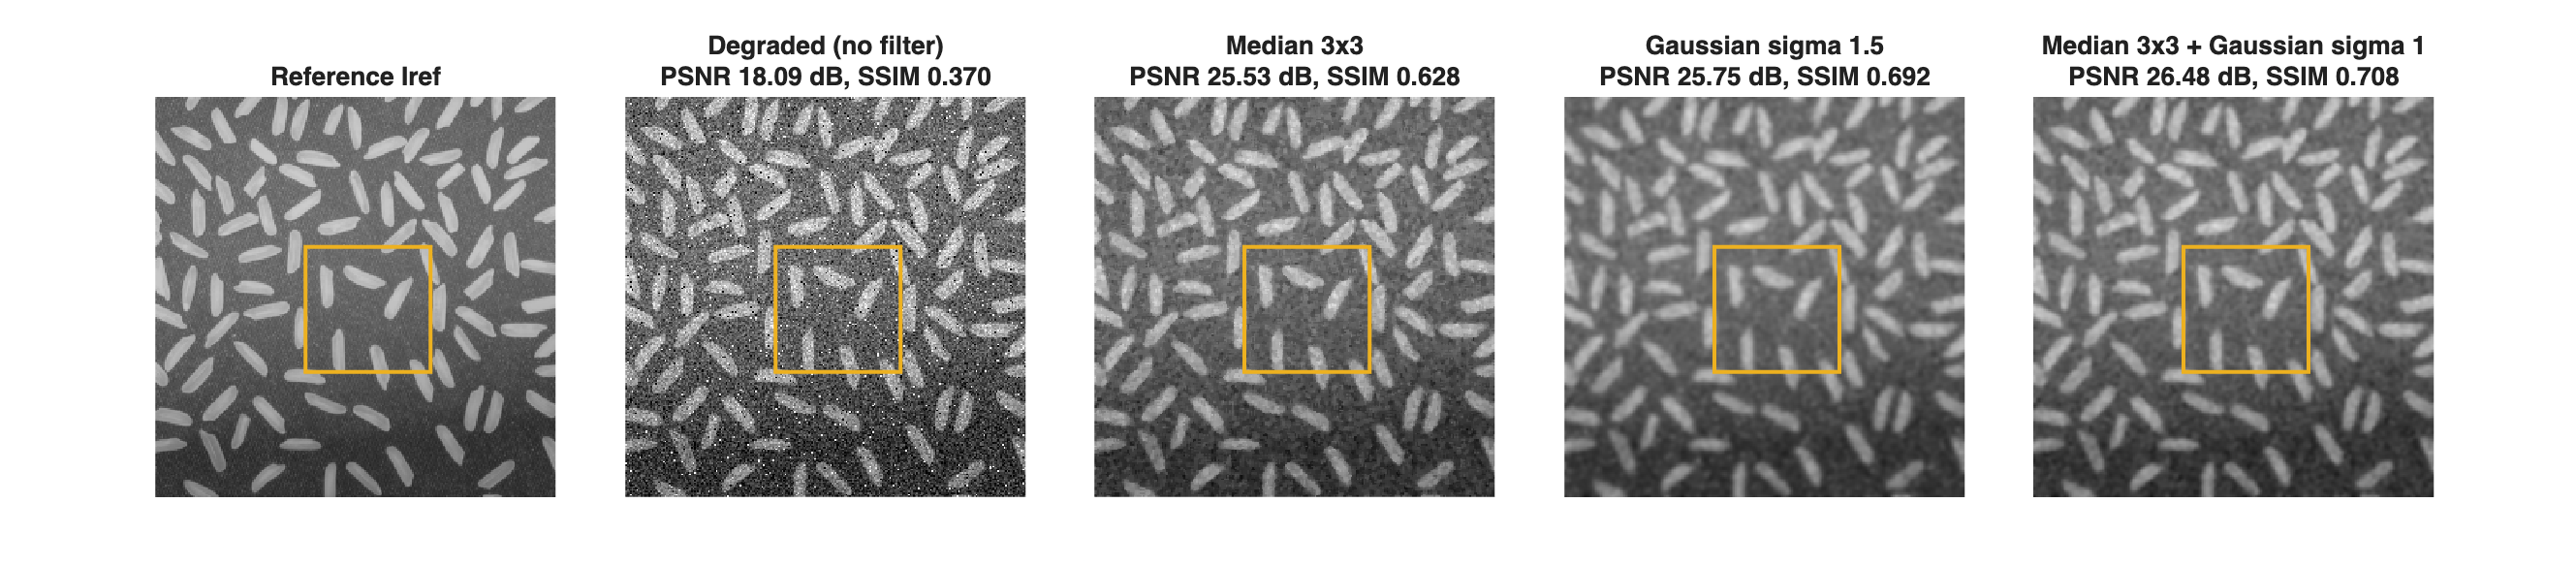


%% Full images
% The yellow square marks the 80x80 region that is enlarged below.

zoomRows = 97:176;
zoomCols = 97:176;
zoomRect = [zoomCols(1) - 0.5, zoomRows(1) - 0.5, numel(zoomCols), numel(zoomRows)];

allNames  = [{'Reference Iref'}; names];
allImages = [{Iref}; images];

fig = figure('Position', [100 100 1500 330]);
theme(fig, 'light');
tiledlayout(1, 5, 'TileSpacing', 'compact', 'Padding', 'compact');
for k = 1:numel(allImages)
    nexttile;
    imshow(allImages{k});
    rectangle('Position', zoomRect, 'EdgeColor', [0.9290 0.6940 0.1250], 'LineWidth', 1.5);
    if k == 1
        title(allNames{k});
    else
        title(sprintf('%s\nPSNR %.2f dB, SSIM %.3f', allNames{k}, psnrDb(k - 1), ssimVal(k - 1)));
    end
end
exportgraphics(fig, fullfile(resultsDir, 'fig1_full_images.png'), 'Resolution', 150);

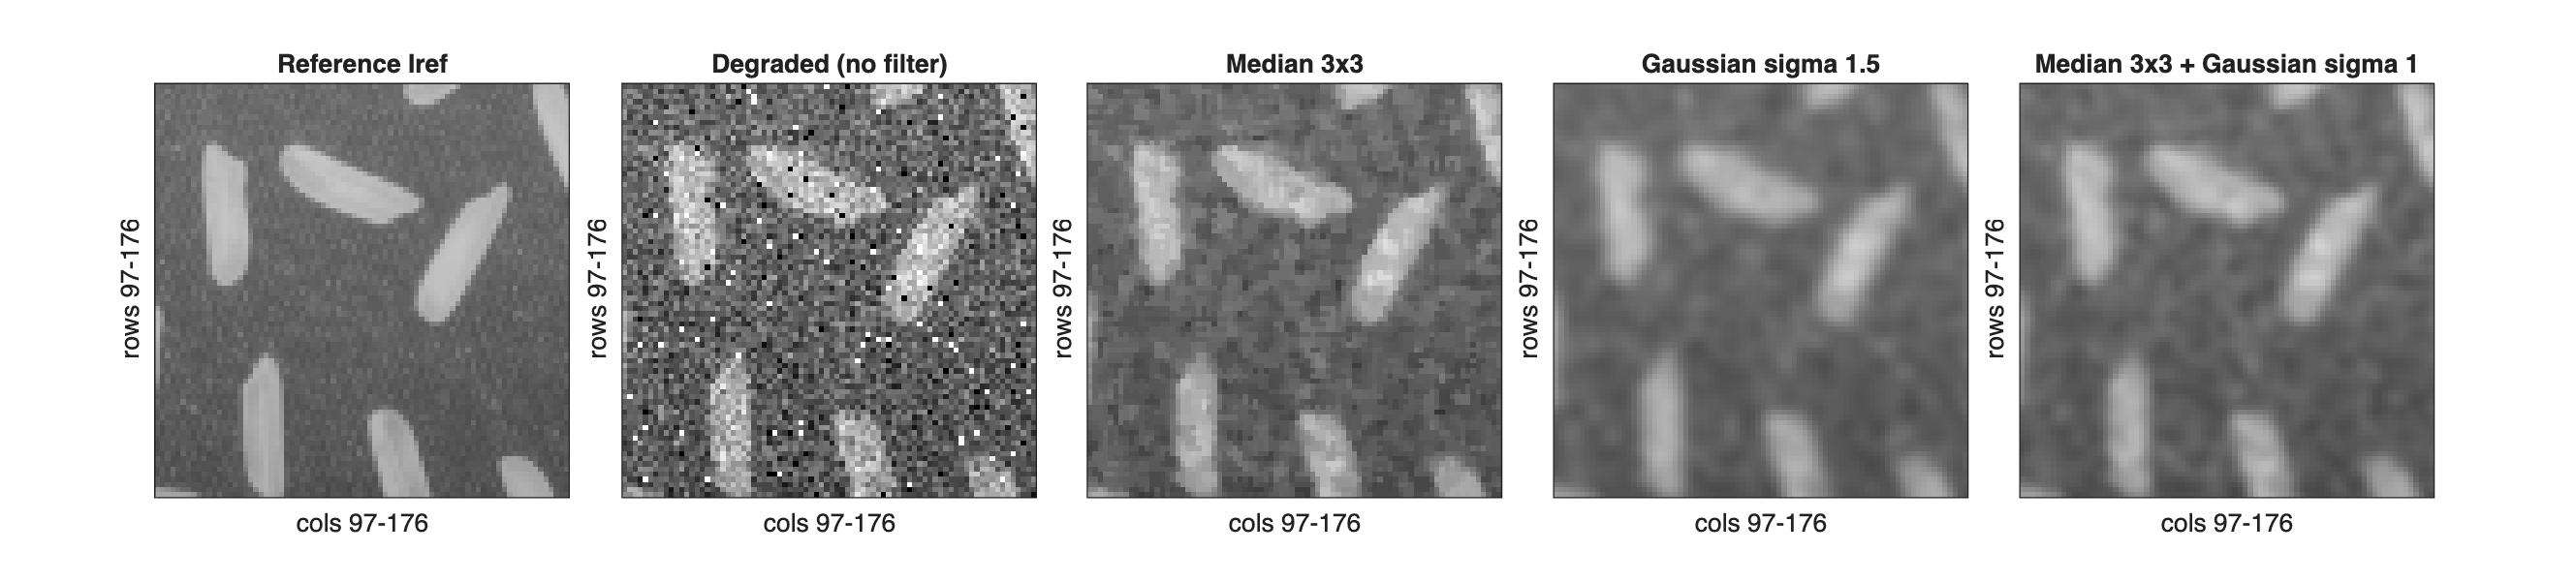


%% Zoomed region (80x80 pixels)
% Nearest-neighbour display, so every pixel is visible. Look for isolated
% black or white dots (remaining impulses), a grainy texture in the
% background (remaining Gaussian noise) and soft grain outlines (blur).

fig = figure('Position', [100 100 1500 340]);
theme(fig, 'light');
tiledlayout(1, 5, 'TileSpacing', 'compact', 'Padding', 'compact');
for k = 1:numel(allImages)
    nexttile;
    imshow(allImages{k}(zoomRows, zoomCols), 'InitialMagnification', 'fit');
    set(gca, 'Visible', 'on', 'XTick', [], 'YTick', []);
    title(allNames{k});
    xlabel(sprintf('cols %d-%d', zoomCols(1), zoomCols(end)));
    ylabel(sprintf('rows %d-%d', zoomRows(1), zoomRows(end)));
end
exportgraphics(fig, fullfile(resultsDir, 'fig2_zoom_80x80.png'), 'Resolution', 150);

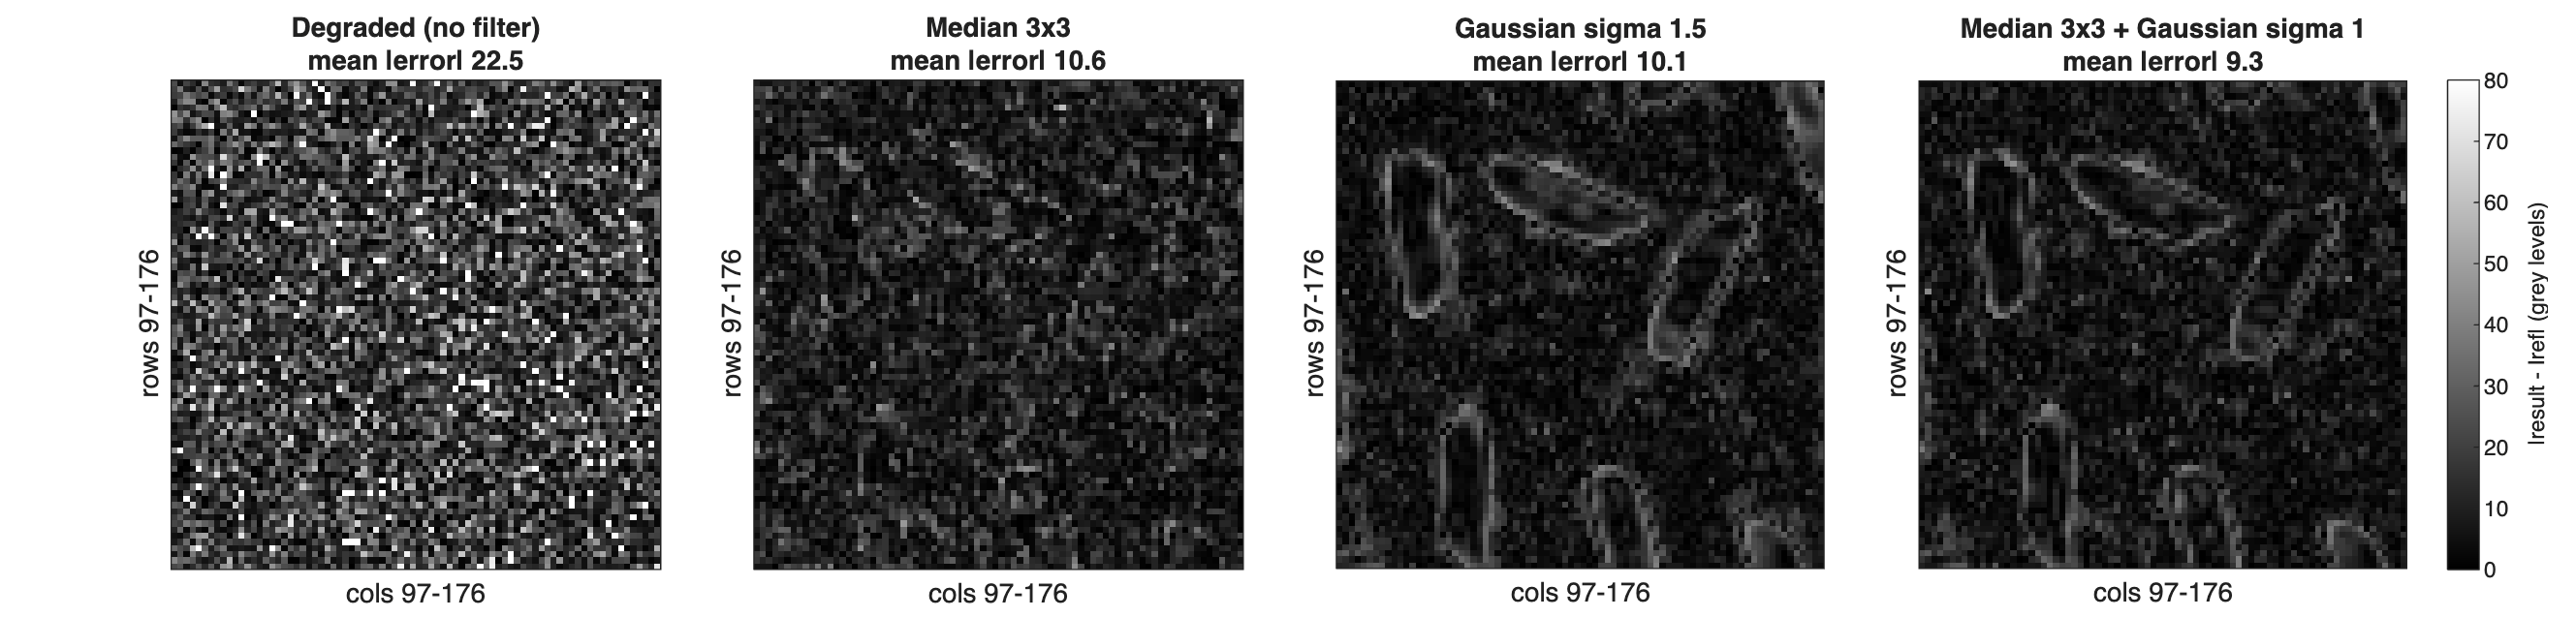


%% Absolute error against Iref
% Bright pixels are large errors. Remaining impulses appear as dots or
% blobs, blur appears as bright outlines along the grain edges, and
% remaining Gaussian noise appears as speckle everywhere. All panels share
% the colour range 0-80 grey levels.

fig = figure('Position', [100 100 1500 360]);
theme(fig, 'light');
tiledlayout(1, 4, 'TileSpacing', 'compact', 'Padding', 'compact');
for k = 1:numel(images)
    nexttile;
    err = abs(double(images{k}) - double(Iref));
    imagesc(err(zoomRows, zoomCols), [0 80]);
    axis image; colormap(gca, gray);
    set(gca, 'XTick', [], 'YTick', []);
    title(sprintf('%s\nmean |error| %.1f', names{k}, mean(err(:))));
    xlabel(sprintf('cols %d-%d', zoomCols(1), zoomCols(end)));
    ylabel(sprintf('rows %d-%d', zoomRows(1), zoomRows(end)));
end
cb = colorbar;
cb.Layout.Tile = 'east';
cb.Label.String = '|result - Iref| (grey levels)';
exportgraphics(fig, fullfile(resultsDir, 'fig3_error_maps.png'), 'Resolution', 150);


%% Discussion
% *Measured results (R2026b).* All three filters improve the degraded image
% (18.09 dB, SSIM 0.370). Median 3x3 reaches 25.53 dB / 0.628, Gaussian
% sigma 1.5 reaches 25.75 dB / 0.692, and median 3x3 + Gaussian sigma 1
% reaches 26.48 dB / 0.708, the best on both metrics.
%
% *Median 3x3.* The median of nine neighbours ignores a few extreme values,
% so the salt-and-pepper impulses disappear and grain edges stay sharp. An
% impulse survives only if five of the nine pixels in its window are
% impulses of the same type, which is very rare at 2 % density. A median
% is much weaker against Gaussian noise: the zoomed background and grains
% keep a clearly grainy texture, and the error map shows speckle
% everywhere. This is why the median alone scores lowest of the three. The
% Gaussian noise touches every pixel, while the impulses affect only 2 %
% of them, so the noise that the median leaves behind dominates the error.
%
% *Gaussian sigma 1.5.* A weighted average cannot reject an outlier, so each
% impulse is spread into a faint grey blob rather than removed. The strong
% kernel smooths the Gaussian noise well, which gives it a higher PSNR and
% a clearly higher SSIM than the median. The cost is blur: the grain
% outlines are soft in the zoomed region and appear as bright rims in the
% error map.
%
% *Median 3x3 followed by Gaussian sigma 1.* The median removes the impulses
% first, so the following Gaussian filter only has to smooth the remaining
% Gaussian noise. A smaller sigma is enough, so the grain rims in the error
% map are weaker than with sigma 1.5. Compared with the Gaussian filter
% alone it gains 0.73 dB PSNR and 0.016 SSIM.
%
% *Preferred filter: median 3x3 + Gaussian sigma 1.* It is the best on both
% metrics and handles both noise types: the median removes the impulses and
% the Gaussian removes most of the grain. Some noise remains as a faint,
% blotchy texture in the background, and the grain edges are slightly
% softer than in |Iref|. The gain over Gaussian sigma 1.5 is small (0.73
% dB), so the visible difference is mainly that the edges are sharper and
% no impulse blobs remain.
%
% *Limitation.* The comparison uses one image, one noise realisation
% (|rng(42)|) and one fixed setting per filter. PSNR and SSIM need a clean
% reference, which a real noisy photo does not have, and neither metric
% fully matches what a viewer notices: PSNR rewards smoothing of the large
% flat background even when grain edges get softer.

